# Altman Z - Credit Worthiness

The Altman Z-score is a formula for determining whether a company, notably in the manufacturing space, is headed for bankruptcy. 

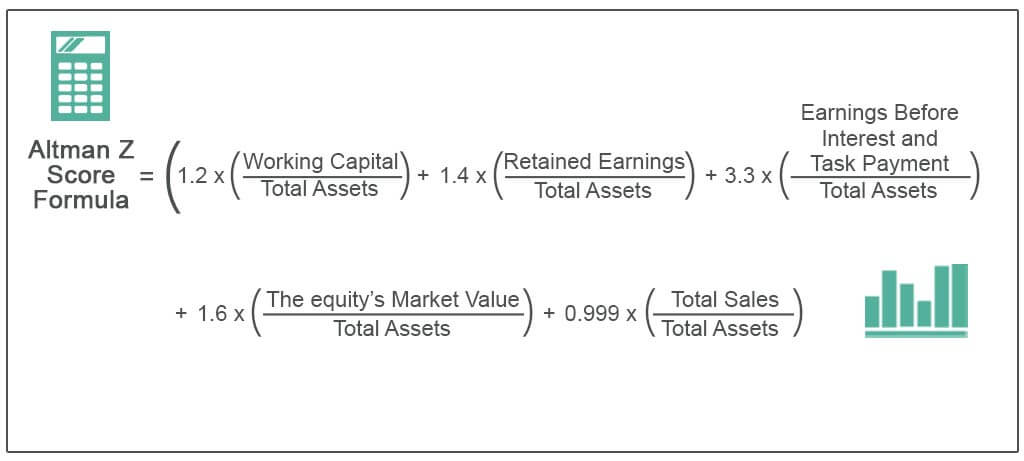

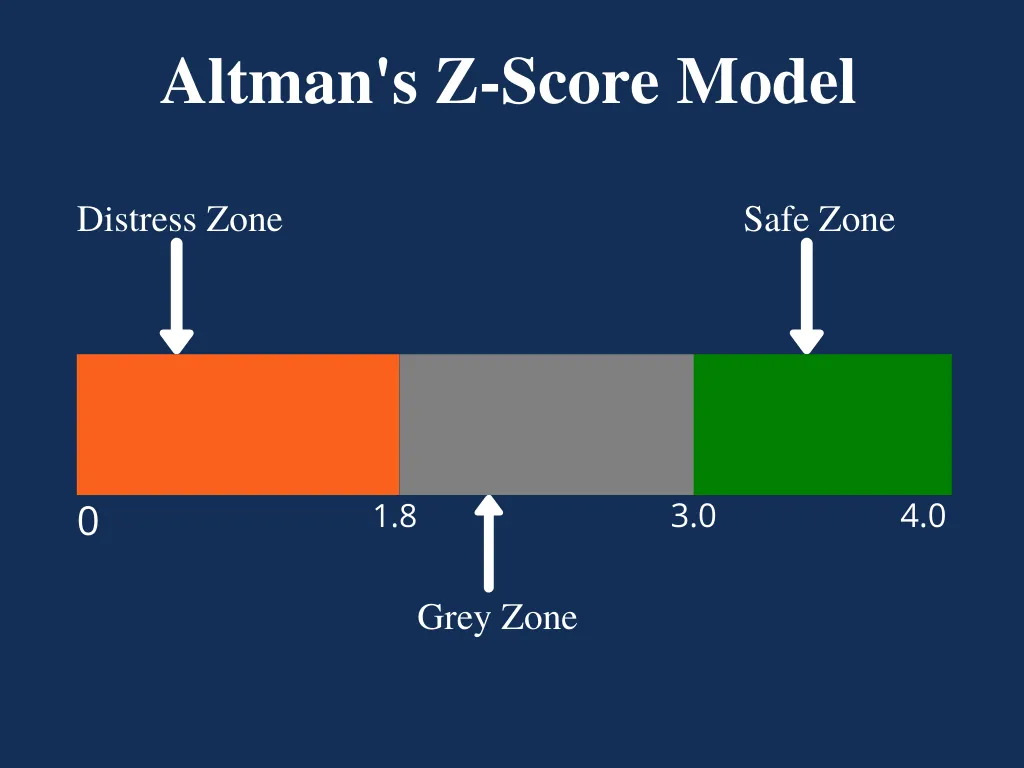

## Merge Data

Credit = importCreditRating('CreditPortfolio','Credit Rating');
Portfolio = importPortfolioInfo('CreditPortfolio','Portfolio Information');
Data = innerjoin(Credit,Portfolio);
clear Credit Portfolio

## Create Factors & Response Table

Data = [Data(:,2:7) Data(:,'Rating')];
Data.Rating = categorical(Data.Rating,{'CCC','B','BB','BBB','A','AA','AAA'},'Ordinal',true);

## Estimate Altman Z-Score & Define Good vs. Bad Companies

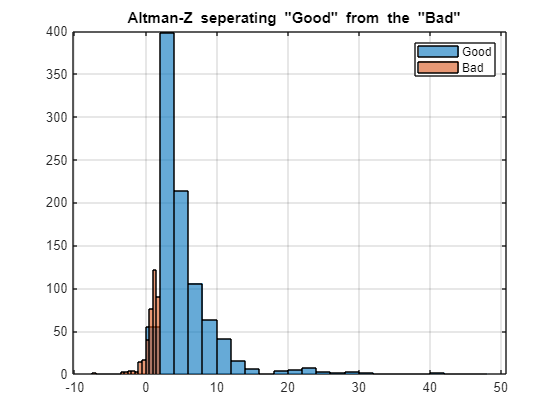

zFactors    = zscore(Data{:,1:end-1});
Zscore      = 1.2*Data.WC_TA + 1.4*Data.RE_TA + 3.3*Data.EBIT_TA + 1.6*Data.MVE_BVTD + 0.999*Data.S_TA;
I_Good      = Zscore > 1.8;
createAltmanZPlot(Zscore(I_Good,:), Zscore(~I_Good,:))

## Create a logistic regression on data

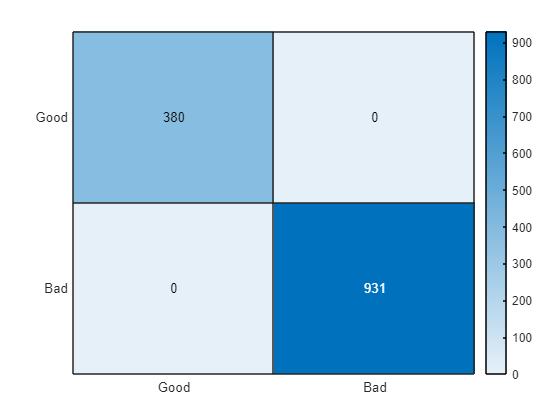

[B,dev,stats]            = mnrfit(zFactors,categorical(I_Good),'link','logit','model','ordinal');
[pihat,dlow,dhi]         = mnrval(B,zFactors,stats,'link','logit','model','ordinal');
[Prob,RatingIdx]         = max(pihat,[],2);
Rating                   = RatingIdx - 1;
RatingCategories         = ["Good"; "Bad"];
Matrix_ActualVsEstimated = confusionmat(Rating,double(I_Good));
figure
heatmap(RatingCategories,RatingCategories,Matrix_ActualVsEstimated)